1

clear;
clc;
a0 = 1;
f = @(x,u) [x(2,:);a0 .* (sin(x(1,:) + u .* cos(x(1,:))))];
a = 1;
s = @(x) a*x(1,:)+x(2,:);
beta0 = 1;
sat = @(u)min(1,max(-1,u));
u = @(x) sat(-(a.*abs(x(2,:))./(0.5.*cos(x(1,:)))+tan(x(1,:))+beta0).*sat(s(x)/0.1)/2)*2;
x0 = [pi/6;0];
tfinal = 5;
sol = ode45(@(t,x)f(x,u(x)),[0,tfinal],x0);
t = sol.x;
x = sol.y;


fimplicit(@(x1,x2)s([x1;x2]),[-1,1],'--')

figure();
plot(t,x(1,:),t,x(2,:));
legend('x1','x2');
figure();
plot(t,u(x));
figure();
plot(t,s(x));

2

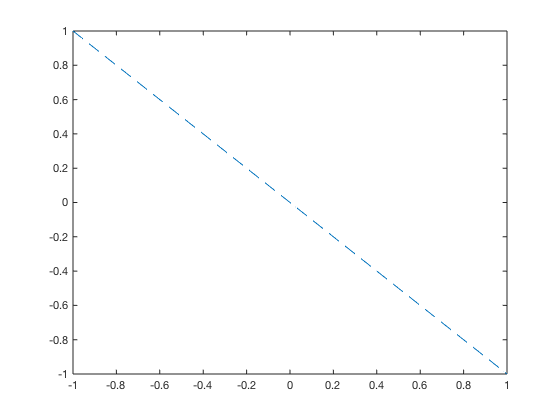

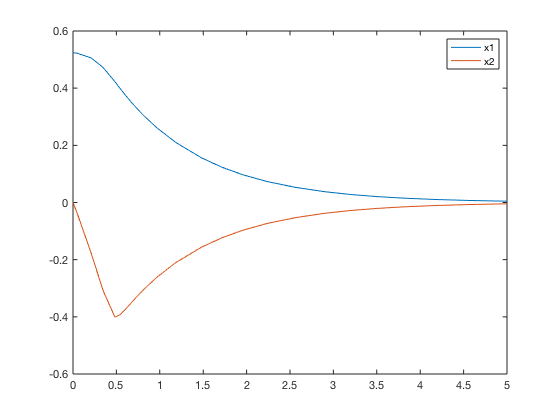

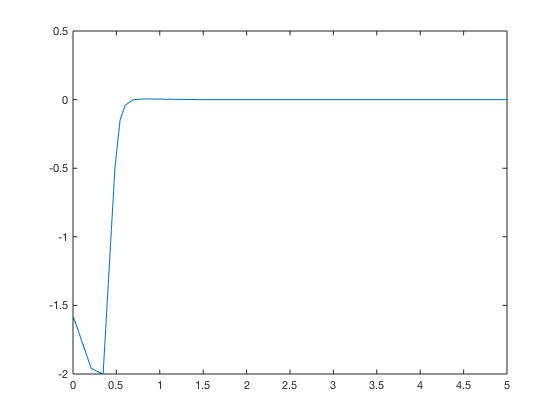

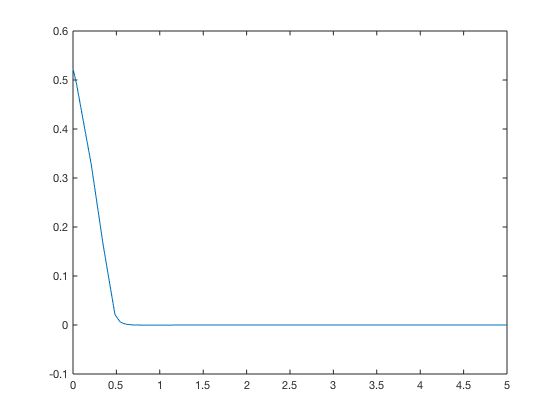

clear variables
syms x [2,1]
syms xhat [2,1]
syms t
a0 = 1;
beta0 = 1;
% sat = @(u)min(1,max(-1,u));
a = 1;
symmin =  @(x,y)feval(symengine,'min',x,y);
symmax =  @(x,y)feval(symengine,'max',x,y);

s(x1,x2) =symmin(1,symmax((a*x1+x2),-1)) ;


%((0<x1)) &(
% s(x1,x2)=piecewise((a*x1+x2)/0.1>1,1,(a*x1+x2)/0.1)
% piecewise_function = @(x) (x.^2+x) .* ((0<x) & (x<1));
%  s(x1,x2)= (a*x1+x2)/0.1+(-(a*x1+x2)/0.1+1).*((a*x1+x2)/0.1>=1)%+(-(a*x1+x2)/0.1-1).*((a*x1+x2)/0.1<=-1);
u(x1,x2) = symmin(2,symmax((-(a.*abs(x2)./(0.5.*cos(x1))+tan(x1)+beta0).*s(x1,x2)),-2));

f(x1,x2) = [x2;a0 * (sin(x1) + u(x1,x2) * cos(x1))];
h(x1,t) = x1 + 0.05*sin(20*t);
% A = jacobian(f,x);
% A = A(xhat1,xhat2);
 A= [0 1;1*cos(xhat1)  0];
C = [1,0];

syms P [2,2]
P=(P+P')/2; % to ensure that P is symmetric
Q = 3*eye(2);
R = 1;
dP = A*P+P*A'+Q-P*C'/R*C*P;
dPv = reshape(dP,4,1);% vectorizing
H = P*C'/R;
fhat = f(xhat1,xhat2)+H*(x1-xhat1);
F = matlabFunction([f;fhat;dPv],'Vars',{t,[x1;x2;xhat1;xhat2;P1_1;P1_2;P2_1;P2_2]});
x0 = [pi/6;0];
P0 = 30*eye(2);
xhat0 = [pi/6;0];
X0 = [x0;xhat0;P0(:)];
tf = 10;
options = odeset('OutputFcn','odeplot','OutputSel',1:4);
figure()
sol = ode45(F,[0,tf],X0,options);
xlabel('t')
legend('x1','x2','xhat1','xhat2')
clear;
syms x [2,1]
syms xhat [2,1]
syms t
a0 = 1;
beta0 = 1;
% sat = @(u)min(1,max(-1,u));
a = 1;
symmin =  @(x,y)feval(symengine,'min',x,y);
symmax =  @(x,y)feval(symengine,'max',x,y);

s(x1,x2) =symmin(1,symmax((a*x1+x2),-1)) ;


%((0<x1)) &(
% s(x1,x2)=piecewise((a*x1+x2)/0.1>1,1,(a*x1+x2)/0.1)
% piecewise_function = @(x) (x.^2+x) .* ((0<x) & (x<1));
%  s(x1,x2)= (a*x1+x2)/0.1+(-(a*x1+x2)/0.1+1).*((a*x1+x2)/0.1>=1)%+(-(a*x1+x2)/0.1-1).*((a*x1+x2)/0.1<=-1);
u(xhat1,xhat2) = symmin(2,symmax((-(a.*abs(xhat2)./(0.5.*cos(xhat1))+tan(xhat1)+beta0).*s(xhat1,xhat2)),-2));

f(x1,x2) = [x2;a0 * (sin(x1) + u(x1,x2) * cos(x1))];
h(x1,t) = x1 + 0.05*sin(20*t);
% A = jacobian(f,x);
% A = A(xhat1,xhat2);
 A= [0 1;0.5*cos(xhat1)  0];
C = [1,0];

syms P [2,2]
P=(P+P')/2; % to ensure that P is symmetric
Q = 3*eye(2);
R = 1;
dP = A*P+P*A'+Q-P*C'/R*C*P;
dPv = reshape(dP,4,1);% vectorizing
H = P*C'/R;
fhat = f(xhat1,xhat2)+H*(x1-xhat1);
F = matlabFunction([f;fhat;dPv],'Vars',{t,[x1;x2;xhat1;xhat2;P1_1;P1_2;P2_1;P2_2]});
x0 = [pi/6;0];
P0 = 30*eye(2);
xhat0 = [pi/6;0];
X0 = [x0;xhat0;P0(:)];
tf = 10;
options = odeset('OutputFcn','odeplot','OutputSel',1:4);
figure()
sol = ode45(F,[0,tf],X0,options);

xlabel('t')
legend('x1','x2','xhat1','xhat2')